load('glass_prop.mat')
load('small_set.mat')

%declaration of global variables
global beaker_volume beakerinnerdim beakerouterdim beakerheight mantel_A;
global top_A Tinf humidity k_glass rho_glass cp_glass epsilon_glass;

beaker_volume = glass.beaker_size(1); %m3
beakerinnerdim = glass.inner_diameter(1); %m
beakerouterdim = glass.outer_diameter(1); %m
beakerheight = glass.height(1); %m
[mantel_A, top_A] = coffeCupArea(beakerheight,beakerouterdim,beakerinnerdim);
Tinf = 20.6+273; %room temprature C 
humidity = 0.22; %room humidity
k_glass = glass.heat_conduction;
rho_glass = glass.density;
cp_glass = glass.heat_capacity;
epsilon_glass = glass.emissioncoeff;

% Initial values for temperature and mass
y0 = [(273.15+80),0.126];

% Time interval where the ODE is solved
tint = [1 2250];

% ODE solver
[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

current heat flux mantel -0.037 k/s
 current heat flux top -0.052 k/s 
current mass flux -0.01089 g/s
Current temp and mass 353.1 K 126.0 g 
 
current heat flux mantel -0.035 k/s
 current heat flux top -0.044 k/s 
current mass flux -0.00909 g/s
Current temp and mass 349.1 K 125.5 g 
 
current heat flux mantel -0.033 k/s
 current heat flux top -0.042 k/s 
current mass flux -0.00850 g/s
Current temp and mass 347.7 K 125.4 g 
 
current heat flux mantel -0.028 k/s
 current heat flux top -0.029 k/s 
current mass flux -0.00578 g/s
Current temp and mass 339.6 K 124.4 g 
 
current heat flux mantel -0.026 k/s
 current heat flux top -0.026 k/s 
current mass flux -0.00508 g/s
Current temp and mass 336.9 K 124.1 g 
 
current heat flux mantel -0.025 k/s
 current heat flux top -0.024 k/s 
current mass flux -0.00475 g/s
Current temp and mass 335.6 K 123.9 g 
 
current heat flux mantel -0.026 k/s
 current heat flux top -0.027 k/s 
current mass flux -0.00528 g/s
Current temp and mass 337.7 K 124.3 g 
 

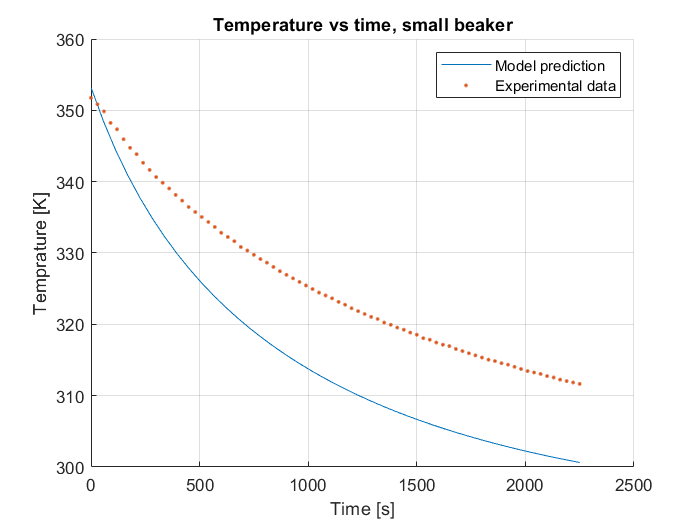

%Plotting experimental data vs modell for temperature
figure(1)
hold on
plot(t,Y(:,1))
plot(small(2).beaker(:,1)*60,small(2).beaker(:,2)+273.15,'.')

title('Temperature vs time, small beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on
hold off

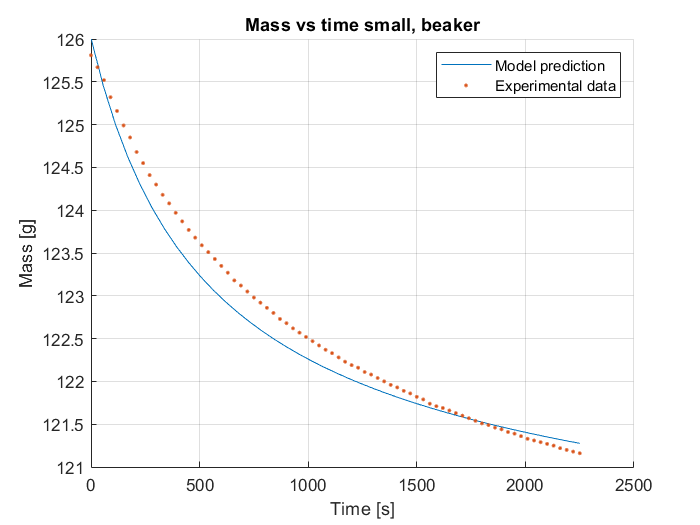

%Plotting experimental data vs modell for mass
figure(2)
hold on
plot(t,Y(:,2)*1000)
plot(small(2).beaker(:,1)*60,small(2).beaker(:,3),'.')

title('Mass vs time small, beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on
hold off